clear;clc;close all;
rng(1);
N=50;

データの準備　xの両端で0，1に収束しない方が自然であるデータを作る

xVals=[randn(2*N,1)-1;
    rand(N,1)*6-3;
    randn(2*N,1)+0.5;
    rand(N,1)*6-3;
    ];
yVals=[zeros(2*N,1);zeros(N,1);
    ones(2*N,1);ones(N,1)];
ind =randperm(size(xVals,1));
xVals=xVals(ind);
yVals=yVals(ind);
bins=-5:0.1:5;

figure;
scatter(xVals,yVals);hold on;grid on;
set(gca,'fontname','メイリオ')

mdl=glmfit(xVals,yVals,"binomial")

mdl =     0.0974
    0.7122


plot(bins, glmval(mdl,bins,"logit"))
syms p a_0 a_1 c x y

2PLM

p=1/(1+exp(-a_0-a_1*x))

$$p = \frac{1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}$$

誤差をそれぞれのパラメータで偏微分した関数を作る

dpda_0=diff((p-y)^2,a_0)

$$dpda\_0 = -\frac{2\,{\mathrm{e}}^{-a_{1}\,x-a_{0}}\,\left(y-\frac{1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}\right)}{{\left({\mathrm{e}}^{-a_{1}\,x-a_{0}}+1\right)}^{2}}$$

dpda_1=diff((p-y)^2,a_1)

$$dpda\_1 = -\frac{2\,x\,{\mathrm{e}}^{-a_{1}\,x-a_{0}}\,\left(y-\frac{1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}\right)}{{\left({\mathrm{e}}^{-a_{1}\,x-a_{0}}+1\right)}^{2}}$$

データごとに偏微分の値を評価し，パラメータを更新する．

subs関数は動作が遅いが，プログラムを簡単にするため多用している．

a_0Val=0;a_1Val=0;rho=0.05;
for k=1:15
    ind =randperm(size(xVals,1));
    xVals=xVals(ind);
    yVals=yVals(ind);
    for n1=1:N
        a_0Val=a_0Val-rho*subs(dpda_0, ...
            [x y a_0 a_1],[xVals(n1) yVals(n1) a_0Val a_1Val]);
        a_1Val=a_1Val-rho*subs(dpda_1, ...
            [x y a_0 a_1],[xVals(n1) yVals(n1) a_0Val a_1Val]);
        a_0Val=double(a_0Val);
        a_1Val=double(a_1Val);
    end
end

うまく収束させるためにはrhoの調整が必要だが，ここでは行っていない

(ので，glmfitの結果と少しずれる)

[a_0Val;a_1Val]

ans =     0.1741
    0.6358


plot(bins, ...
    subs(subs(p,[a_0 a_1],[a_0Val a_1Val]),bins),'--')

3PLM

予測勝率にパラメータcを含める

p3=c+(1-2*c)/(1+exp(-a_0-a_1*x))

$$p3 = c-\frac{2\,c-1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}$$

dpda_0=diff((p3-y)^2,a_0)

$$dpda\_0 = \frac{2\,{\mathrm{e}}^{-a_{1}\,x-a_{0}}\,\left(2\,c-1\right)\,\left(y-c+\frac{2\,c-1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}\right)}{{\left({\mathrm{e}}^{-a_{1}\,x-a_{0}}+1\right)}^{2}}$$

dpda_1=diff((p3-y)^2,a_1)

$$dpda\_1 = \frac{2\,x\,{\mathrm{e}}^{-a_{1}\,x-a_{0}}\,\left(2\,c-1\right)\,\left(y-c+\frac{2\,c-1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}\right)}{{\left({\mathrm{e}}^{-a_{1}\,x-a_{0}}+1\right)}^{2}}$$

dpdc=diff((p3-y)^2,c)

$$dpdc = 2\,\left(\frac{2}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}-1\right)\,\left(y-c+\frac{2\,c-1}{{\mathrm{e}}^{-a_{1}\,x-a_{0}}+1}\right)$$

a_0Val=0;a_1Val=0;cVal=0;rho=0.05;
for k=1:15
    ind =randperm(size(xVals,1));
    xVals=xVals(ind);
    yVals=yVals(ind);
    for n1=1:N
        a_0Val=a_0Val-rho*subs(dpda_0, ...
            [x y a_0 a_1 c], ...
            [xVals(n1) yVals(n1) a_0Val a_1Val cVal]);
        a_1Val=a_1Val-rho*subs(dpda_1, ...
            [x y a_0 a_1 c], ...
            [xVals(n1) yVals(n1) a_0Val a_1Val cVal]);
        cVal=cVal-rho*subs(dpdc, ...
            [x y a_0 a_1 c], ...
            [xVals(n1) yVals(n1) a_0Val a_1Val cVal]);

        a_0Val=double(a_0Val);
        a_1Val=double(a_1Val);
        cVal=double(cVal);
        if cVal<0
            cVal=0;
        end
    end
end

[a_0Val;a_1Val;cVal]

ans =     0.1838
    0.8917
    0.1309


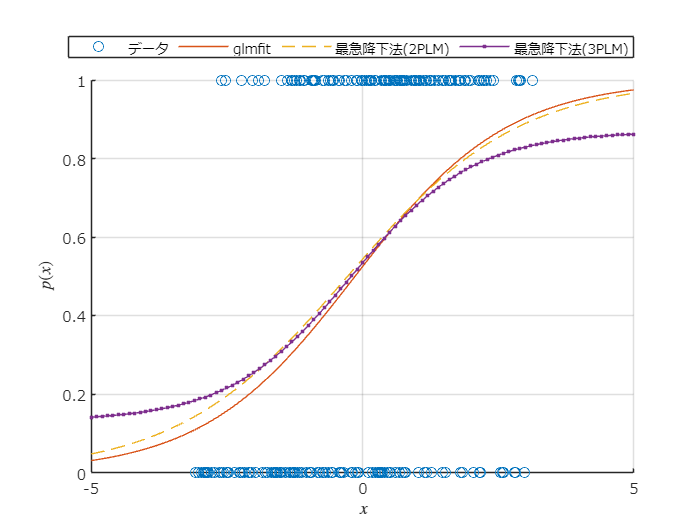

plot(bins, ...
    subs(subs(p3,[a_0 a_1 c],[a_0Val a_1Val cVal]),bins),'.-');
legend({'データ','glmfit','最急降下法(2PLM)','最急降下法(3PLM)'}, ...
    'Location','northoutside','Orientation','horizontal');
xlabel('$x$','Interpreter','latex');
ylabel('$p(x)$','Interpreter','latex');
exportgraphics(gcf,'fig_steepestDescent_PLM.pdf');

最低・最高勝率がc, 1-cで収束するようなモデルを構築できている．